# Clustering project: Hyperspectral Images (HSI) processing  

**Authors:**

• **PSALLIDAS KYRIAKOS**  **, STUDENT ID: 7115152200033**  

# Introduction

**Material Provided:**

- The “Salinas” Hyperspectral image (HSI), which depicts an area of the Salinas valley in California, USA. This image is given  in a 3-D matrix containing $22.500$ pixels in $150x150x204$ cube. Sub-matrix $150x150$ corresponds to the position of each pixel and the $20$4 size vector holds the Hypertspectral values for each pixel in the range of ultraviolet, visible, and near-infrared regions of the electromagnetic spectrum.

load Salinas_Data

- Eight ground-truth classes: “Corn,” two types of “Broccoli,” four types of “Lettuce” and “Grapes,” denoted by different colors in the following figure, there is no available ground truth information for the dark blue pixels.   

- An $150x150$ which contains the above labels for each pixel. 

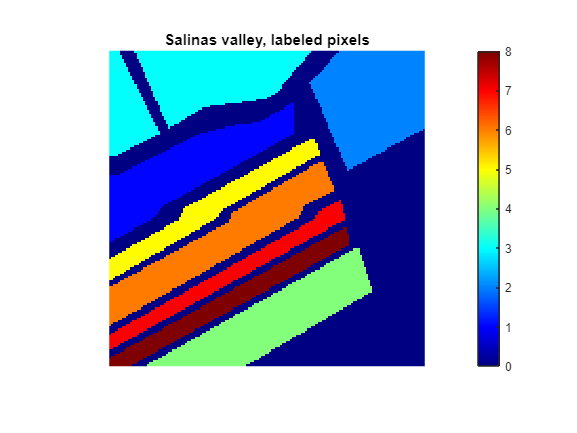

figure;
colormap("jet");
imagesc(Salinas_Labels), axis equal
axis off
title('Salinas valley, labeled pixels')
colorbar

Cluster 0 (dark blue), corresponds to pixels without a ground truth. The rest are as follows:

Labels = {  1, 'Brocoli 1'; 2, 'Brocoli 2'; 3, 'Grapes'; 4, 'Corn' ; 5, 'Lettuce 1'; 6, 'Lettuce 2'; 7, 'Lettuce 3'; 8, 'Lettuce 4'};
cell2table(Labels,'VariableNames', {'Cluster_Number';'Class_Label'})

ans = 8×2 table
    Cluster_Number     Class_Label 
    ______________    _____________

          1           {'Brocoli 1'}
          2           {'Brocoli 2'}
          3           {'Grapes'   }
          4           {'Corn'     }
          5           {'Lettuce 1'}
          6           {'Lettuce 2'}
          7           {'Lettuce 3'}
          8           {'Lettuce 4'}


When discussing the ground truth in the context of clustering, it is important to note that clustering is an unsupervised learning problem. Therefore, the ground truth serves a similar purpose as a test set in supervised learning tasks. Its main use is to evaluate the performance of the different clustering methods and to compare their results, but it should not be used to tune the parameters of the algorithms to mimic the ground truth.

## **Goal**

- Comparisson of the performance of cost function optimization clustering algorithms  **VS **the hierarchical algorithms , At the Identification of the homogenus crop regions in the Salins valley in California.

- Execute the algorithms.

- Identify problems each algorithm faces and why

- Verify Qualitatively the results of each algorithm by comparing:  their visualization with the ground truth image (using external information) and/or the visualization of the PCA components (using only internal information).

- Verify Quntatively the results by: Matching the image labels between.

- Comment on the difference in the performance of the above algorithms.

# **Feeling the Data**

We prepare the data-set for clustering by reshaping the provided Salinas cube matrix to a3-D matrix where the rows correspond to each pixel and the columns to its spectral value across the 204 bands. Additionally we drop the pixels that correspond to the 0 class, where no ground truth exists.

[p,n,l]=size(Salinas_Image);
X_total=reshape(Salinas_Image, p*n,l);
L=reshape(Salinas_Labels,p*n,1);
existed_L=(L>0);  
X=X_total(existed_L,:);
[px,nx]=size(X)

px = 13908

nx = 204

Ground_truth = L(existed_L);

## Descriptive statistics

Having reshaped the HSI cube into a 3-D martix we can plot the probability density function of each spectral band. From the approximated pdfs below,

It's evident that the largest density of values lie on the visible spectrum with two-three small peaks in the infared spectrum. Additionally most of the values range between 0 and 1500 $\mu m$.

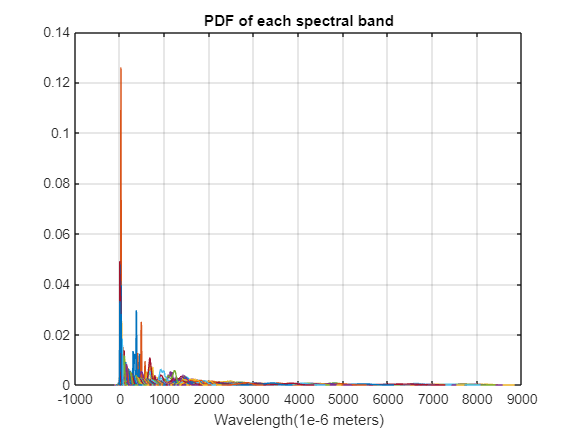

figure;
for i = 1:204
    ksdensity(X(:,i))
    hold on
    grid on
end
xlabel('Wavelength(1e-6 meters)')
title('PDF of each spectral band')
hold off

The largest  value of a spectral band is 8374, while the smallest -9.

max(max(X))

ans = 8374

min(min(X)) 

ans = -9

However the mean values of the spectral bands lie close together.

mean_array = mean(X);
std(mean_array)

ans = 1.2217e+03

## Mean normalization

Sine we have a large value range for the spectral bands and our goal is to evaluate different clustering algorithms, normalazation is advised. For example some distance based clustering algorithms such as k-means is sensitive to large distances and may converge slower.  

We utilize mean normalization: $\frac{x-\bar{x}}{max(x)-min(x)}$

X_total = (X_total - mean(X_total)/max(X_total) - min(X_total));
X=X_total(existed_L,:);

## Principal Component Analysis 

Having performed normalization, since we are dealing with 204 dimensions, its a good idea to attempt dimensionality reduction with PCA.

- The `explain` variable in PCA analysis holds information on the percentage of the cumulative variance of the original dataset that each of the Principal Components (PCs) captures. This can provide insight into the linear relationships present in the data and the contribution of each PC to the overall variation in the dataset.

- Z and Y contain the row vectors of X and X_total projected to the dimension space of the PCs.

[~,~,explain,Z,~]= pca_fun(X',3);
[~,~,explain_total,Z_total,~] = pca_fun(X_total',2);
%PCs without the zero class 
size(Z')

ans =        13908           3


%PCs with the zero class
size(Z_total')

ans =        22500           2


Notice how in both cases, for the total dataset (X_total) and when excluding 0 pixels (X), 100% of the total variance can be summed up by the first three Principal Components.

array2table(explain(1:3)','VariableName', {'first_PC','second_PC','third_PC'} )

ans = 1×3 table
    first_PC    second_PC    third_PC 
    ________    _________    _________

    0.93706     0.057976     0.0025985


array2table(explain_total(1:3)','VariableNames', {'first_PC','second_PC','third_PC'} )

ans = 1×3 table
    first_PC    second_PC    third_PC 
    ________    _________    _________

    0.91184      0.08126     0.0036189


We can also plot the projected pixels into the3-D space of the 3 PCs, where the clusters formed in this space do not necessarily match the original clusters in the 204-D space. This is because the preservation of variance does not guarantee the preservation of clusters. Ηοwever we can note that 7-8 clusters are formed.

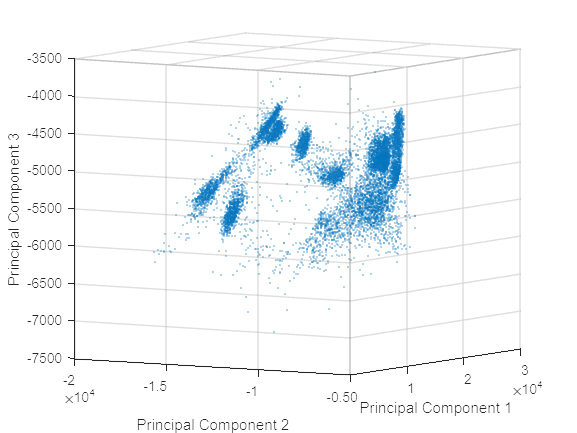

PCA = figure;
scatter3(Z(1,:),Z(2,:),Z(3,:),'.','MarkerEdgeAlpha',0.3)
colormap("jet")
grid on 
xlabel('Principal Component 1')
ylabel('Principal Component 2')
zlabel('Principal Component 3')
view([58 -6])

In order to provide a visual reference of the clusters identified in the Salinas Valley dataset, we will plot the corresponding depiction of the first Principal Component which captures `93.7. `

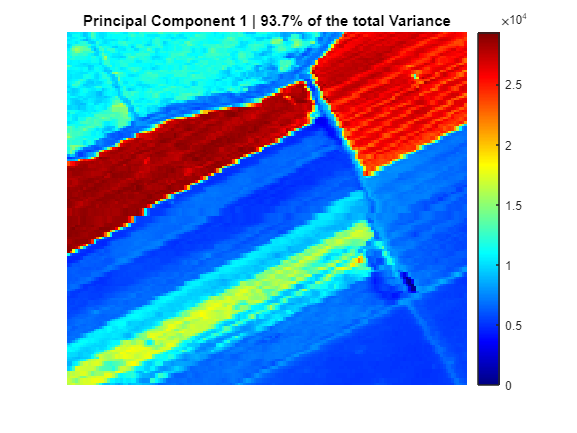

%reshaping the data back to pixel coordinates
Z_total_cube = reshape(Z_total',150,150,2);
PC_1_figure = figure;
imagesc(Z_total_cube(:,:,1))
colorbar
axis off
colormap("jet")
title('Principal Component 1 | 93.7% of the total Variance')
colorbar 

# Determining the number of physical clusters 

## Elbow method  K-means

First we run the k-means algorithm, using the elbow method. Both on the 204-D original dataset and on the 3-D dataset from the PCA.

The elbow method is a  method used to determine the optimal number of clusters . The method is based on the idea that the the cost function of the k-means algorithm: $J(U,\Theta ) = \sum_{i=1}^N\sum^m_{j=1}u_{ij}||x_i-\theta_j||^2$ will decrease as the number of clusters increases.This is because, as the number of clusters increases, there are more representatives present for points to be assigned to and their distance from them will decrease, resulting in a lower cost function value. However, at a certain point, the cost function value will level off and will not decrease significantly as the number of clusters increases. The reason behind that fact is that additional representatives will end up in the same "physical" cluster, which will result in the small intra cluster distances between  points and their original representative to become slightly smaller. 

- Below we run 40 experiments with 10  iterations of the k-means algorithm  for a number of clusters from 2 to 10. 

- Following that we take the mean of the cost function corresponding to each cluster number from the 40 experiments and plot it vs the cluster numbers. 

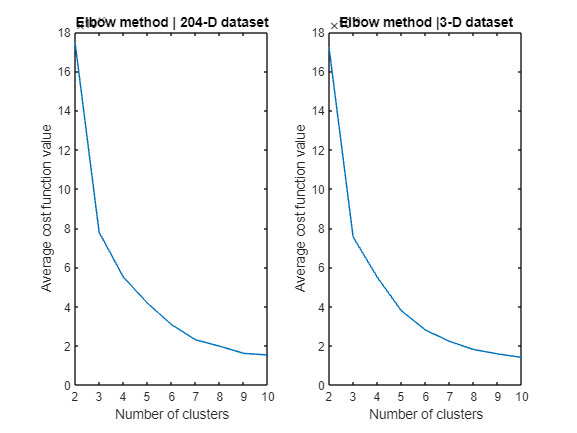

cost_stacked_total = [];
cost_stacked_PCA = [];
%original dataset
for i = 1:40
    cost_total = [];
    for k = 2:10
        [idx, ~, cost] = kmeans(X, k);
        cost_total = cat(1, cost_total, sum(cost));
    end
    cost_stacked_total = cat(2,cost_stacked_total,cost_total);
end
% PCA projected dataset
for i = 1:40
    cost_total = [];
    for k = 2:10
        [idx, ~, cost] = kmeans(Z', k);
        cost_total = cat(1, cost_total, sum(cost));
    end
    cost_stacked_PCA = cat(2,cost_stacked_PCA,cost_total);
end
mean_cost_stacked_total = mean(cost_stacked_total,2);
mean_cost_stacked_PCA = mean(cost_stacked_PCA,2);
%plotting
subplot(1,2,1);
plot(2:10, mean_cost_stacked_total);
title("Elbow method | 204-D dataset")
xlabel('Number of clusters')
ylabel('Average cost function value')
xticks(1:15)
subplot(1,2,2);
plot(2:10,mean_cost_stacked_PCA)
title("Elbow method |3-D dataset")
xticks(1:15)
xlabel('Number of clusters')
ylabel('Average cost function value')

From the plot above, it is clear that the optimal cluster number is around 4-6 in both the original 204-D dataset and in the3-D dataset resulting from the PCA. Even though the rate of decrease in the cost function value becomes lower after the 3-cluster case, it still remains significant. Therefore, we do not consider the 3-cluster solution as optimal. It is important to note that the goal of clustering is also a significant factor in this context. In this case, our aim is to identify homogeneous regions in the Salinas Valley, which translates to the highest number of clusters/homogeneous areas that still provide an optimal solution. 

## Silhouette Method  K-means

Now that we have a rough idea about the optimal number of clusters we can become more certain by further evaluation. A useful method is the silhouette  method, used to evaluate the quality of clustering by measuring the coherence of clusters. It is done by calculating the silhouette coefficient, which ranges from -1 to 1. 

-  A coefficient close to  1  indicates more coherent clusters

-  A  coefficient close to 0 indicates that the outer points of a cluster are in the boundary with another cluster 

- Negative values indicates cluster overlap.

The Silhouette coefficient is based on two metrics: cluster cohesion and cluster separation. 

- Cohesion is the average distance between an instance and all other data points within the same cluster, for each $x$ in a cluster $C_i$ it is calculated as: $a(x) = \frac{\sum_{x\in C_i}d(x,x_\not \in C_i)}{|C_i| - 1}$

- Separation is the average distance between an instance and all other data points $x$  in the nearest cluster $C_j$: $b(x) = min \frac{\sum_{x \in C_j}d(x,x_{\in C_j})}{|C_j|}  $

Silhouette coefficient for a specific clustering is finally calculated as the average score across all clusterd instances $x\;$ of seperation minus cohesion over the maximum between cohesion and seperation : $s = \frac{1}{N}\sum_i^n\frac{b(i) -a(i)}{max(a(i),b(i))$

Having defined the Silhouete method, we use the MATLAB `evalclusters` method to find the average Silhouette coefficient per number of clusters for both the original 204-D dataset and the PCA projected3-D dataset, with the `k-means` algorithm.

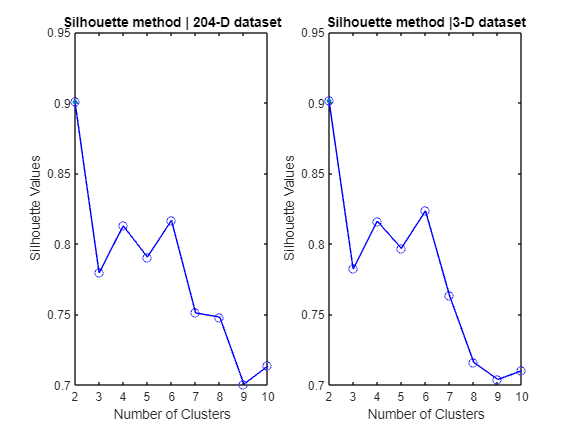

evaluation_total = evalclusters(X,"kmeans","silhouette","KList",1:10);
evaluation_PCA = evalclusters(Z',"kmeans","silhouette","KList",1:10);
figure;
subplot(1,2,1);
plot(evaluation_total)
title("Silhouette method | 204-D dataset")
xticks(1:10)
subplot(1,2,2);
plot(evaluation_PCA)
xticks(1:10)
title("Silhouette method |3-D dataset")

As before, we will disregard the 2 cluster solution as the optimal number, due to the reasons previously stated. The clustering evaluation results obtained from both the original and the projected dataset appear to be identical. Based on these results, the optimal cluster number for our goal of identifying homogeneous regions in the Salinas Valley is 6, as it is the largest cluster number that still demonstrates optimal performance

## Silhouette Methomd Hierarchical 

Finally, in order to account for non-spherical cluster shapes, we will run the same evaluation as previously described using a hierarchical framework.

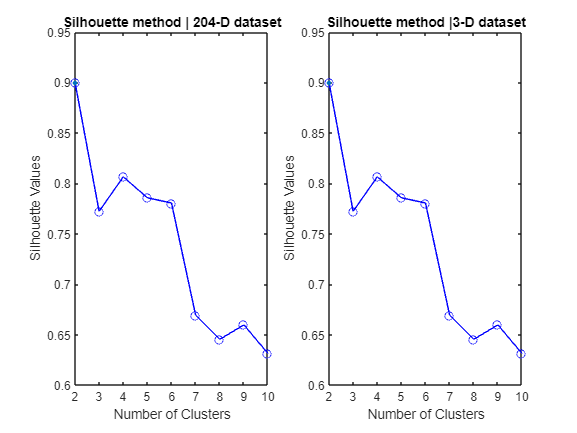

evaluation_total = evalclusters(X,"linkage","silhouette","KList",1:10);
evaluation_PCA = evalclusters(Z',"linkage","silhouette","KList",1:10);
figure;
subplot(1,2,1);
plot(evaluation_total)
title("Silhouette method | 204-D dataset")
xticks(1:10)
subplot(1,2,2);
plot(evaluation_total)
xticks(1:10)
title("Silhouette method |3-D dataset")

Based on the results of our analysis, it appears that 4 clusters may be the optimal number for identifying homogeneous regions in the Salinas Valley. However, the 6 cluster case still demonstrates a relatively high Silhouette score and is the highest cluster number before a significant decrease in performance. 

- We conclude that the optimal cluster number for this task is 6. This number is consistently the larger cluster number before an abrupt drop in the rate of decrease of the cost function with the elbow method as well as a drop in Silhouette values for proceeding cluster numbers.

-  The3-D projected dataset, obtained from the PCA of the original 204-D dataset, seems to maintain the physical clusters present in the 204-D space, as demonstrated by the similarities of all three evaluation methods in both dimensionalities.

# Execution of the Algorithms & Qualitative evaluation

**Clustering in the space spanned by the three first Principal Components**

The3-D projected dataset, obtained from the PCA of the original 204-D dataset, appears to maintain the physical clusters. To improve computational efficiency while preserving the effectiveness of the Eucledian distance, which diminishes in high dimensional spaces, we will continue with the  execution of the algorithms in the space spanned by the first three principal components.

When considering only the first two PCs, notice how Ground thruth class label 4, is split into two physical clusters in the 2-D space with an inbetween class label(7) and additionally it overlaps greatly with class label 5. 

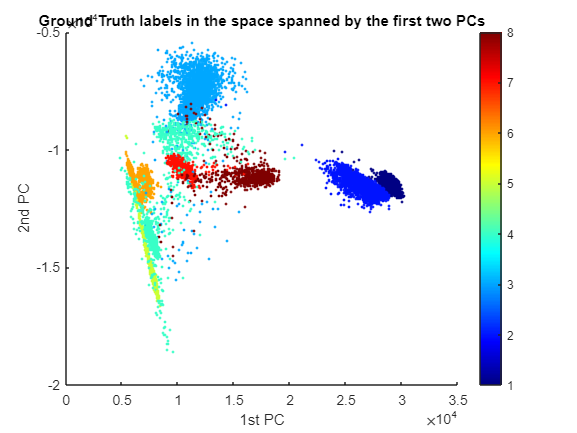

figure;
scatter(Z(1,:),Z(2,:),'CData',Ground_truth,'MarkerEdgeAlpha',0.9,'Marker','.')
title('Ground Truth labels in the space spanned by the first two PCs')
xlabel("1st PC")
ylabel("2nd PC")
colormap("jet")
colorbar

With the introduction of the 3rd PC axis, which only capturs 0.36% of the total variance, we have greater seperation of the ground truth clusters. This could mean that cluster above the otimal number of 6 ( as we have found from the analysis) are formed from spectral band values that are very close to each other.

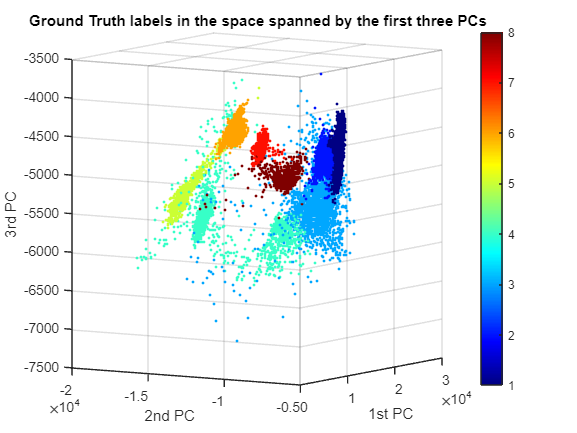

figure;
scatter3(Z(1,:),Z(2,:),Z(3,:),'CData',Ground_truth,'Marker','.')
title('Ground Truth labels in the space spanned by the first three PCs')
xlabel("1st PC")
ylabel("2nd PC")
zlabel("3rd PC")
colormap("jet")
colorbar
view([58 -6])

**Comments on the Execution of the Algorithms**

- In order to evaluate the performance of the different clustering algorithms, each algorithm was executed for both the 6 cluster case, which was found to be optimal from our analysis above, and the 8 cluster case, which corresponds to the ground truth.

- For the cost function  optimization algorithms (CFO), each algorithm was executed  with random seed values from 1 to 15 and the best run according to the average silhouette coeficinet value was picked in order to discard "bad" runs caused by  faulty initial condition and pick optimal cases.  Faulty initial conditions are for example bad placement of initial representatives in the case of k-means and fuzzy c-means and poor local optimum from the Expectation Maximiazation (EM) algorithm in the case of probabilistic clustering.

# Cost Function Optimization Algorithms (CFO)

## **K-means**

The k-means algorithm is a hard clustering algorithm that assigns each data point to one and only one cluster. The process begins by randomly selecting initial representatives in the dataset. Each data point is then assigned to the closest representative and the representative is moved to the mean of its assigned points. This process is repeated iteratively until the cost function $J(U,\Theta ) = \sum_{i=1}^N\sum^m_{j=1}u_{ij}||x_i-\theta_j||^2
$ can no longer be decreased, indicating convergence.

The k-means algorithm utilizes the k-means++ algorithm for the initial positioning of the representatives, which ensures that the data points that are farthest from the nearest representative are likely to be selected as a representative position. This results in faster convergence as the initial representatives are already located close to the actual clusters.

Total_idx_kmeans = [];
average_silhouete_score_kmeans = [];
count = 1;
for i = [6,8]
    rand('seed',12)
    idx = kmeans(Z',i,'Distance','sqeuclidean');
    s = silhouette(Z',idx);
    average_silhouete_score_kmeans =  cat(2,average_silhouete_score_kmeans,mean(s));
    Total_idx_kmeans = cat(2,Total_idx_kmeans,idx);
    count = count + 1;
end

 fprintf(" Average Silhouete scores: %s",average_silhouete_score_kmeans)

 Average Silhouete scores: 8.233960e-01 Average Silhouete scores: 7.592500e-01

The best performance of the k-means algorithm with seed number 1 to 15 was obtained using a random seed of 12, with the above Silhouette scores.

**Problems faced 1.**

However, it is important to note that the clustering results of the k-means algorithm are significantly influenced by the initial positioning of the representatives since the cost function mentioned before has many local optimal solutions, which sometimes dont translate to actual clusters. Runs with a Silhouette score of around 5.5 to 6, though less frequent, were observed while iterating from random state of 1 to 15.

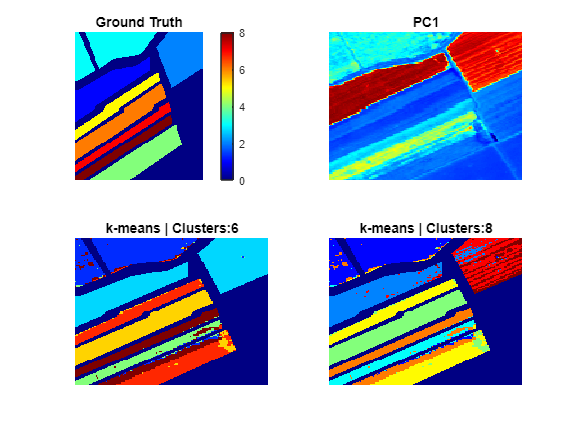

Clustering_Eval(Total_idx_kmeans,'k-means',Z_total_cube,Salinas_Labels,existed_L) 

**Qualitative evaluation**

As it's shown in the figure above, with the right inital representatives, k-means is able to capture a clustering result which is almost identical to the first principal component in the optimal cluster case of k = 6. However for k= 8 it mispredicts class label 5(yellow), and splits, the class label  2 (medium dark blue)  for reasons specified below.

**Problems faced 2.**

 K-means minimizes the sum of squared distances between the data points in a cluster and the cluster's representatives (mean), thus it returns compact clusters with similar size, which might not be the shape of the actual clusters:

The left-most figure provides a visual representation of the original dataset, plotted in the space spanned by the first two principal components, and colored according to their corresponding ground truth labels. It is evident that the k-means clustering algorithm struggles to represent the phsycial clusters when we introduce more representatives than 6, since almost always splits eleipsoid shaped clusters in two or more parts in order to minimize the cost function. 

This is highlighted in the example below:

-  Where the ground truth  classes 2,3  (dark blue and blue) are splitted to three clusters. 

- The Ground Truth class 5 (light green / yellow) and  part of class 4 (green) are grouped together since that results in the most compact shape and the smallest distance from the representatives.

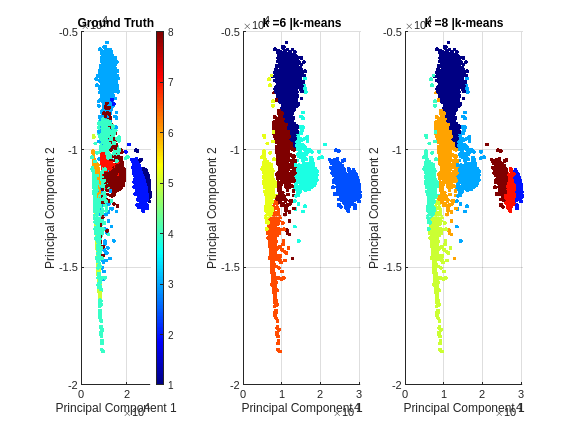

PCA_vs_cluster_plot_2D(Ground_truth,Total_idx_kmeans,Z, 'k-means')

Below is the plot of the actual dimensions of the clustered dataset ( the first three PCs), rotated  to showcase even better the problem just discussed.

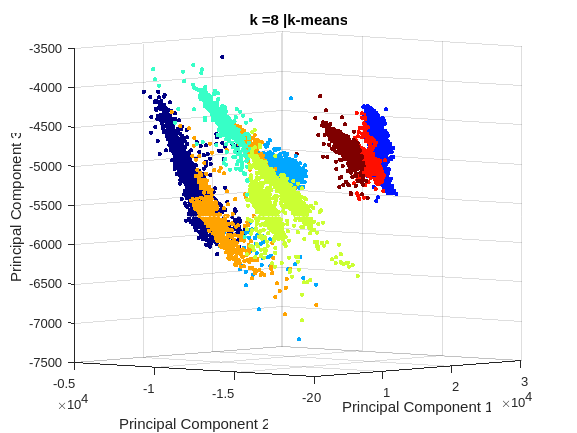

PCA_vs_cluster_plot_3D(Ground_truth,Total_idx_kmeans,Z, 'k-means')
view([-49 4])

## **Fuzzy C-Means**

Unlike k-means, the fuzzy c-means employes a fuzzy framework with a degree of fuzzines $q$ where each point can belong to a cluster to a degree. FCM cost function is similar to the k-means cost function $L_q(U,\Theta) = \sum^N_{i=1}\sum^m_{j=1}u_{ij}^qd(x_i,\theta_j)  + \sum^N_{i=1}\lambda _i(\sum(^m_{j=1}u_{ij} -1)$ and points can take degree of membership values from 0 to 1.

A frequent selected value for q is 2, we run this algorithm with the procedure described in the beggining of the chapter.

**Degree of fuzziness q = 2**

Total_idx_FCM = [];
average_silhouete_score_FCM = [];
%In order: [ degree of fuzziness , iterations, error cutoff, verbosity]
options = [2 100 1e-5 0];
max_values = [];

count = 1;
    for i = [6,8]
        rand('seed',6);
        [~,idx] = fcm(Z',i,options);
        [M,index] = max(idx,[],1);
        max_values = cat(1,max_values,M);
        s = silhouette(Z',index');
        average_silhouete_score_FCM = cat(2,average_silhouete_score_FCM,mean(s));
        Total_idx_FCM = cat(2,Total_idx_FCM,index');
        count = count + 1;
    end

    fprintf(" Average Silhouete scores: %s",average_silhouete_score_FCM)

 Average Silhouete scores: 7.230986e-01 Average Silhouete scores: 7.579897e-01

The best run with random seed 1-15, was the one with seed 12 and the above Silhouete scores for k=6 and k=8 repsectively.

The Strenght of the FCM algorithm is illustrated when the data points are not clearly defined and may belong to multiple clusters. It is particularly useful when the data points have a degree of overlap or vagueness, and a hard assignment to a single cluster is not appropriate. Notice how the case of fuzzy assignment is showcased clearly below. Points close to a cluster representative have very high degree of belongness , while points that are far away from cluster represenatives and close to cluster borders have very low degree of belongness.

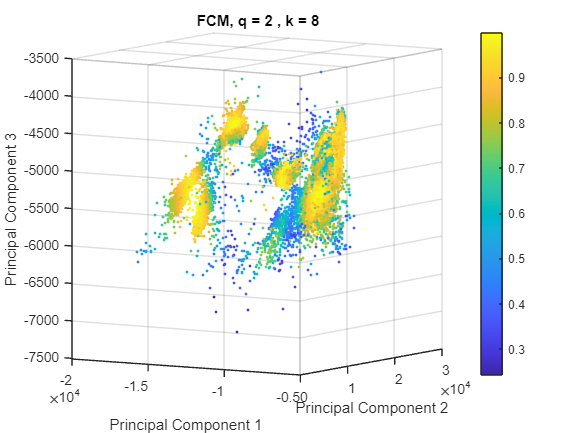

figure;
scatter3(Z(1,:),Z(2,:),Z(3,:),'CData',max_values(2,:),'Marker','.')
colorbar
title("FCM, q = 2 , k = 8")
ylabel('Principal Component 1')
xlabel('Principal Component 2')
zlabel('Principal Component 3')
view([58 -6])

To evaluate the performance of the FCM algorithm, we compared the results of the algorithm to the ground truth labels of the data. To do this, we translated the soft assignments obtained from FCM into hard assignments by identifying the cluster that had the highest degree of membership for each data point. 

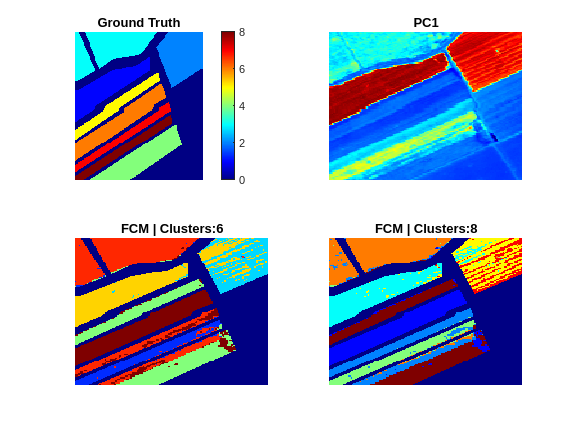

Clustering_Eval(Total_idx_FCM,'FCM',Z_total_cube,Salinas_Labels,existed_L) 

**Qualitative evaluation**

As its depicted above, FCM has a result identical to the k-means case and captures PC1 and homogeneus areas very well. However for the case where k = 8, the FCM run is not optimal since the Ground truth label 3 cluster was again split and class 5 was misspredicted to be the same class as 4, Just like the k-means case. This isn't by chance since FCM, also prioritizes compact clusters with similar sizes, for the reasons discussed in the k-means case.

**Problems faced**

FCM has identical issue with k-means. 

Like k-means, FCM is sensitive to the initial placement of the cluster representatives, and this can greatly affect the final results of the algorithm. 

FCM, much like k-means, uses point representatives to represent each cluster and reduces the mean distance of each point from the cluster representatives as optimization. This results in the recovery of compact clusters. Notice how the resulting clustering is almost idenctical to the k means case.

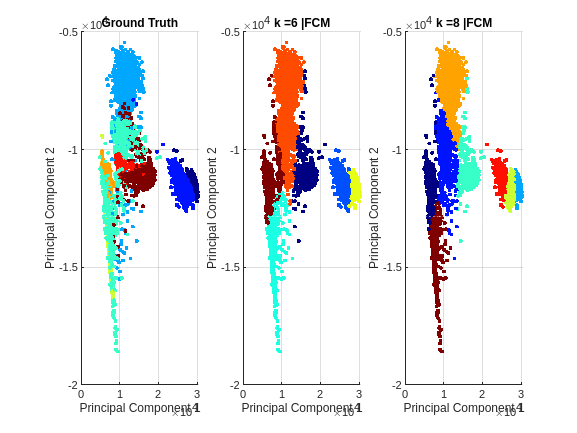

PCA_vs_cluster_plot(Ground_truth,Total_idx_FCM,Z,'FCM')

**Effect of increase in degree of fuzziness q**

It's intresting to see the effect of an increase in degree of fuzziness on the FCM clustering. For this reason, we averaged out 3 runs of the FCM for degree of fuziness $q=\left\lbrack 2\;5\;10\;20\;\right\rbrack$, as its illustrated clearly in this particular dataset an increase in flexibility resulted in cluster overlaps and lower silhouette scores.

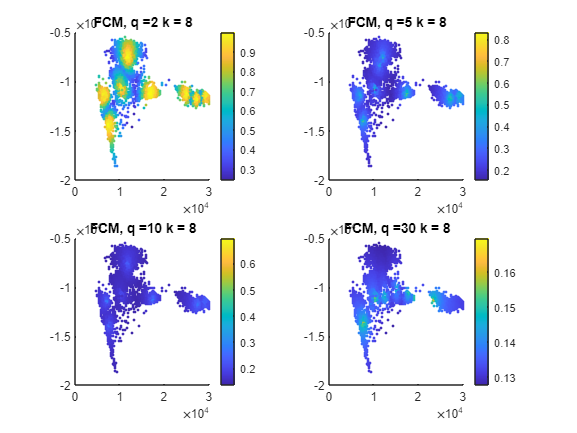

q_s_average = [];
q = [2 5 10 20];
count = 1;
for i = [2 5 10 30]
    options = [i 100 1e-5 0];
    s_average = [];
    for j = 1:3
        [~,idx] = fcm(Z',8,options);
        [M,index] = max(idx,[],1);
        s = silhouette(Z',index');
        s_average = cat(2,s_average,mean(s));
    end 
    subplot(2,2,count);
    q_s_average = cat(2,q_s_average, mean(s_average));
    scatter(Z(1,:),Z(2,:),'CData',M,'Marker','.')
    hold on 
    colormap('default')
    colorbar
    title(strcat('FCM, q = ', int2str(i), ' k = 8'))
    count = count + 1;
end
hold off

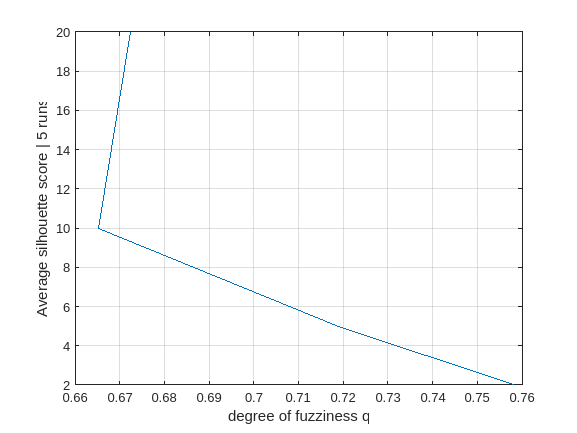

figure;
plot(q_s_average,q);
grid on
xlabel('degree of fuzziness q');
ylabel('Average silhouette score | 5 runs');

## **Possibilistic C-means**

The PCM algorithm utilizes a fuzzy scheme jsut as FCM above, however in the case of PCM the degree of membership for each point to a cluster is not bound between 0 and 1. For this reason the cost function , similar to the one of the FCM also have a regularization user defined constant term $\eta$ associated with the variance of the clusters in order to escape  constant 0 value solutions. 


$$L_q(U,\Theta) = \sum^N_{i=1}\sum^m_{j=1}u_{ij}^qd(x_i,\theta_j)  + \sum^N_{j=1}\eta  _j(\sum(^m_{i=1}1-u_{ij})^q$$


- $\eta \;$can be either the result of a run of the FCM algorithm $\eta _j = \frac{\sum^N_{i=1}u_{ij}^qd(x_i,\theta_j)}{\sum^N_{i=1}u_{ij}^q
$

- Or $\eta  = {\frac{1}{N}\sum^N_{i=1}||x_i - \bar{x}||^2}$

In order not to bias the results of the PCM based on the results of FCM we calculated $\eta$  using the second option. The intialization method which choose vectors X that are the most distant from each other was utilized

 eta = mean((sum(Z' - mean(Z')).^2))

eta = 3.3781e-14

Total_idx_PCM = [];
average_silhouete_score_PCM = [];
max_values = [];
    for i = [6,8]
        %setting the eta parameter to be a  m-dimensional array of the "eta"
        eta_m = ones(1,i)*eta;
        %[U,theta]=possibi(X,m,eta,q,sed,init_proc)
        [idx,~] = possibi(Z, i, eta_m, 2, 4, 3);
        [M,index] = max(idx,[],2);
        s = silhouette(Z',index');
        average_silhouete_score_PCM = cat(2,average_silhouete_score_PCM,mean(s));
        max_values = cat(2,max_values,M);
        Total_idx_PCM = cat(2,Total_idx_PCM,index);
        count = count + 1;
    end
fprintf(" Average Silhouete scores: %s",average_silhouete_score_PCM)

 Average Silhouete scores: 5.560511e-01 Average Silhouete scores: 4.777535e-01

Essentially PCM is an unbound(concerning clustering assignment) Fuzzy means clustering. Points in dense areas are assigned high membership, while points in noisy areas are assigned low membership like FCM, BUT they can also be assigned to no cluster at all. This allows for effective and accurate partitioning of the dataset, even in the presence of noise. PCM can also adjust the number of representatives as necessary for better clustering.  If the number of clusters (k) is less than the actual number of physical clusters, some representatives may not be placed in dense regions, and if k is greater, some naturally formed clusters may be split into multiple parts. In this dataset, while k = 8 only 5 representatives appears wich is again a strong indication that 6 is the optimal cluster number. 

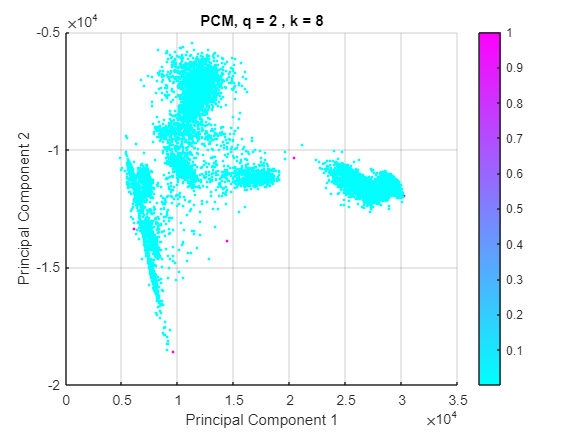

figure;
scatter(Z(1,:),Z(2,:),'CData',max_values(:,1),'Marker','.')
colormap('cool')
grid on
colorbar
title("PCM, q = 2 , k = 8")
xlabel('Principal Component 1')
ylabel('Principal Component 2')

Having the above in mind, the convergance criterion is very abstract and can range from very good to poor solutions. Below is an adequate run of the PCM when compared forr k = 6 and  k = 8 with the Ground truth and the 1st PC.

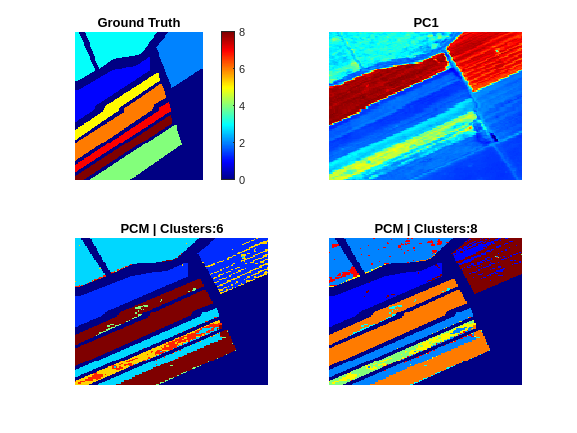

Clustering_Eval(Total_idx_PCM,'PCM',Z_total_cube,Salinas_Labels,existed_L) 

Of course PCM also inherits the problems of the c-means category (k-means, fuzzy c-means) as described before.

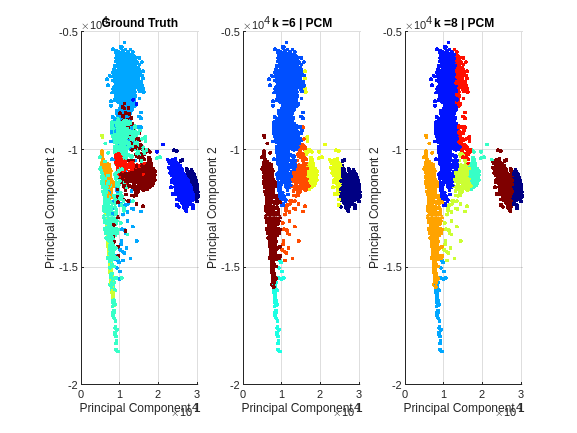

PCA_vs_cluster_plot(Ground_truth,Total_idx_PCM,Z,' PCM')

## **Probabilistic Clustering**

Probabilistic Clustering (PBC)  utilizes a hard probabilistic algorithmic scheme which assumes that the points in the dataset are generated  from a mixture of a finite number of Gaussian distributions with unknown parameters, each one estimates an actual cluster. However  we are not sure in which cluster/distribution each point belongs to, this results in a likelihood estimation of each Gaussian's parameters with missing variables. 

In order to find the parameters in this case and reach a local optima solution the Expectation Maximization algorithm is utilized. In the context of the code, MATLAB's `fitgmdist` method was used to carry out this task. 

It's important to note that the Shilluette score is a much less accurate metric in the probabilistic context  than the negative log likelyhood, which measures  how well a probabilistic model fits a given dataset.

Gaussian Mixture model without independece assumption $\Sigma \neq \sigma ^2I$

Total_idx_PBC_diag = [];
logL_total = [];

for i = [6,8]
    rand('seed',1)
    tic ;
    GMModel = fitgmdist(Z',i,'CovarianceType','full');
    [idx, nLogL] = cluster(GMModel,Z');
    logL = silhouette(Z',idx);
    logL_total = cat(2,logL_total,mean(logL));
    Total_idx_PBC_diag = cat(2,Total_idx_PBC_diag,idx);
end
fprintf(" Negative Log Likelyhood: %s",logL_total)

 Negative Log Likelyhood: 3.961176e-01 Negative Log Likelyhood: 2.533117e-01

Random seed 1, returned the lowest negative likelyhood scores  for the PBC, with no independence assumption. 

**Qualitative evaluation**

PBC with full covariance matrix does not perform very well, it frequently misspredicts grounth truth labels as well as PC1 regions that have similar data distributions in the 3-D space of the dataset. The reason behind this is explain in the following  two "Problems faced" paragraphs.

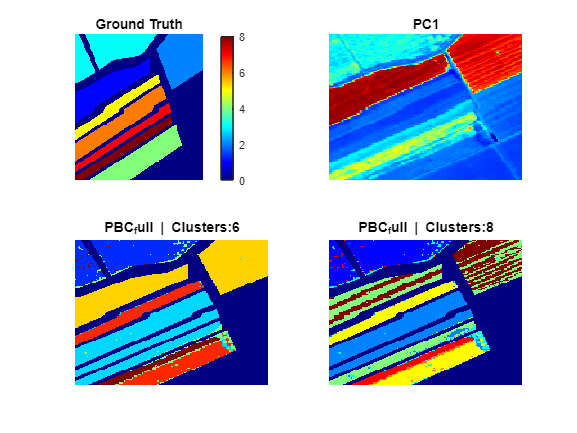

Clustering_Eval(Total_idx_PBC_diag,'PBC_full',Z_total_cube,Salinas_Labels,existed_L) 

**Problems faced 1: **

PCB, without full covariance matrices allows for more complex cluster shapes apart from compact, such as ellipsoids with different variances and correlations between variables in different directions.This has the potentional to increase the clustering performance. However, this added complexity with many more parameters to optimize than just the distance in the k-means case, also increases the risk of the algorithm getting stuck in a suboptimal solution, resulting in inconsistent and unreliable results. Additionally, a low negative log-likelihood, which is often used as a measure of model fit, does not necessarily mean that the identified clusters accurately represent the underlying data as seen in the above results, where we have a lot of misspredictions. This is further explained in Problem 2.

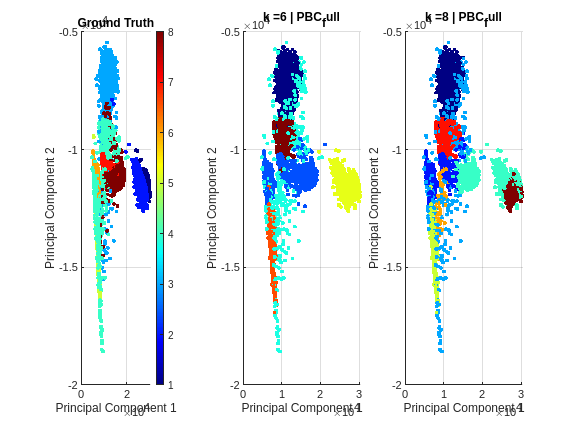

PCA_vs_cluster_plot_2D(Ground_truth,Total_idx_PBC_diag,Z,' PBC_full')

**Problems faced 2:**

PBC as mentioned before uses a finite , in this case 8 distributions and assigns points to the distribution/cluster that has the highest likelyhood of generating them. This has the pitfall that clusters of data with similar shape can be assigned to the same distribution/cluster even though they are well seperated in the clustering space. This is illustrated cearly in the 3D plot below where only the rightmost light green cluster corresponds to a ground truth label. 

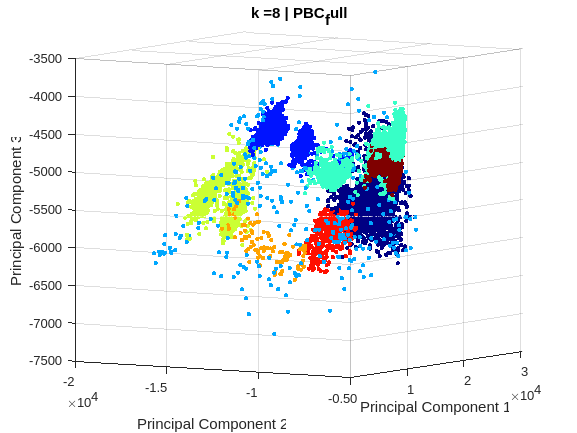

PCA_vs_cluster_plot_3D(Ground_truth,Total_idx_PBC_diag,Z,' PBC_full')

**Solution to problem 1**

A possible solution to problem 1 is to lower the complexity of the model  by assuming feature independence between the feature of our dataset, this results in:

Gaussian Mixture model with independence assumption $\Sigma = \sigma ^2I$

Having diagonal covariance matrices, only the variance and the mean value of each distribution along the 3 axis needs to be fitted and not the covariance between the features, in this case we have 3 less parameters for each distribution. This results in distributions that can still be elipsoid or shperical but cannot be rotated towards a direction. Although that does not escape problem 2 as its clearly depicted below:

Total_idx_PBC_diag = [];
logL_total = [];
count = 1;
for i = [6,8]
    rand('seed',1)
    GMModel = fitgmdist(Z',i,'CovarianceType','full');
    [idx, nLogL] = cluster(GMModel,Z');
    logL = silhouette(Z',idx);
    logL_total = cat(2,logL_total,mean(logL));
    count = count + 1;
    Total_idx_PBC_diag = cat(2,Total_idx_PBC_diag,idx);
end
fprintf(" Negative Log Likelyhood: %s",logL_total)

 Negative Log Likelyhood: 3.961176e-01 Negative Log Likelyhood: 2.533117e-01

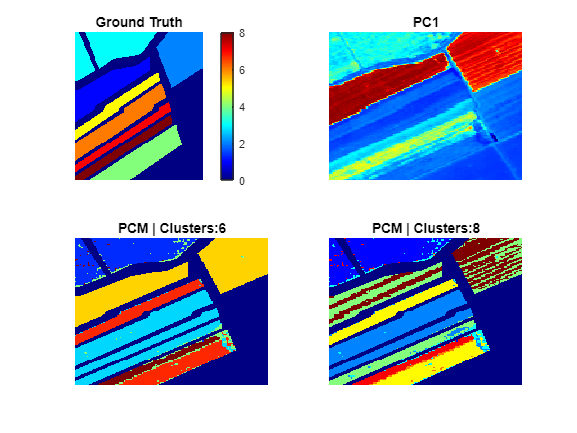

Clustering_Eval(Total_idx_PBC_diag,'PCM',Z_total_cube,Salinas_Labels,existed_L)

# Hierarchical Algorithms

Unlike cost function optimization algorithms, Hierarchical Algorithms are deterministic and produce a single result. This is because the linkage calculation done with `linkage` is a fixed algorithm based on a method and a distance without any random parameters. So for that specific distance and method the result will always be the same.

All the following Hierarchical Algorithms are agglomerative clustering algorithms where they start from each data point as a cluster and in every step they merge the closest clustes based on their particular method and distance metric. This has the drawback that if at a step an innpropriate (based on our goal) cluster merging occurs there is no way of overcoming that issue with the same agglomerative clustering algorithm and distance mertic.

Since the clustering takes places in the 3-D space, euclidean reamains a good distance metric and it is the one used. Additionally Ward algorithm as well as  are optimized for eucledian distance.

## **Ward  algorithm**

The Ward algorithm is an intresting case, since it does not realy directly on a particular distance between cluster points as a mertic for cluster merging but how their merging would affect the within-cluster variance of each cluster.Thus is merges similar clusters. This metric is calculated as the sum of squared distances between the cluster centroids before and after the mege. 

Ward algorithm performs very well, capturing an idendical picture to the 1st Principal component both for k = 6 and k = 8. However when compared to the ground truth while it still perfors very well, we again have the issue of missprediction of ground truth labels 4 and 5 into the same cluster which all methods have faced so far. However a specific problem of Ward is described below.

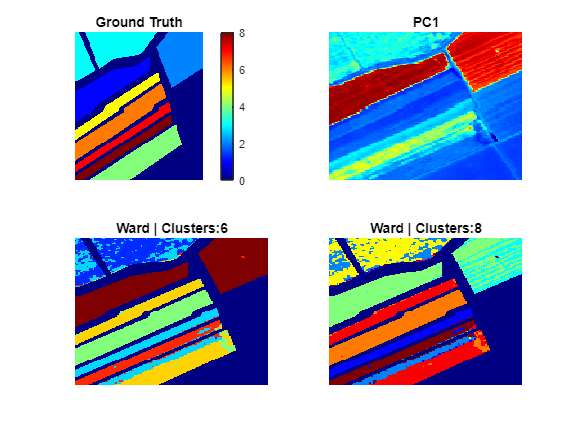

Total_idx_Ward = [];
 for i = [6,8]
    B = linkage(Z','ward','euclidean');
    idx = cluster(B,'maxclust',i);
    Total_idx_Ward = cat(2,Total_idx_Ward,idx);
 end
figure;
Clustering_Eval(Total_idx_Ward,'Ward',Z_total_cube,Salinas_Labels,existed_L) 

**Problem faced **

The ward algorithm splits Ground truth label 3 (light blue) into two clusters, this is because the merging of these two cluters dissimilar clusters produces high with-in cluster variance which the Ward algorithm avoids.

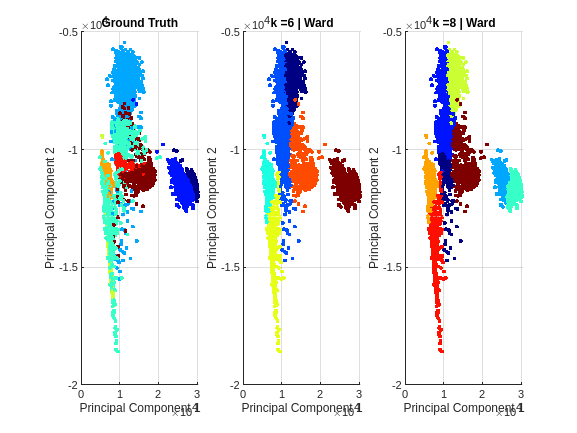

PCA_vs_cluster_plot(Ground_truth,Total_idx_Ward,Z,' Ward')

This problem is cleary visible when inspecting the full 3 dimensions of our projected dataset,  notice how yellow cluster is dissimilar to the blue cluster and thus its not merged , as it is in the Ground Truth.

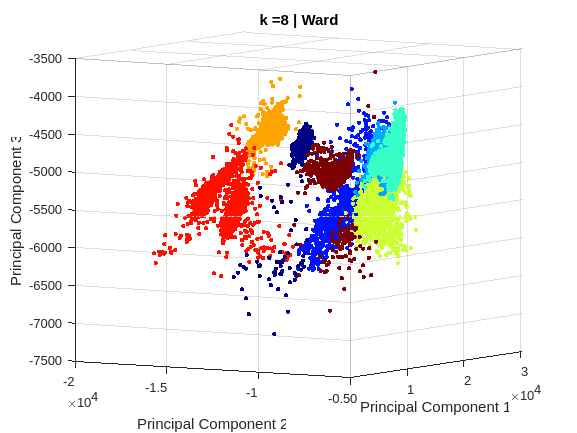

PCA_vs_cluster_plot_3D(Ground_truth,Total_idx_Ward,Z,' Ward') 

**Complete Link algorithm**

The Complete Link method employs a stringent criterion for merging clusters at each step, which is defined as the minimum distance between the farthest points of the cluster pairs being considered for merging at that particular step.

Complete link produces a much batter result for k = 6 than k = 8 both when compared to PC1 and the Ground Truth.

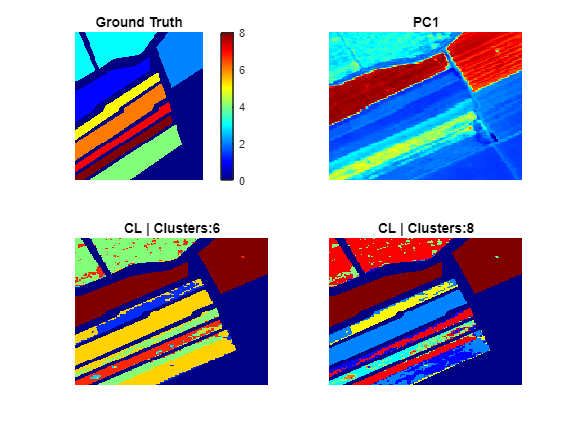

Total_idx_CL = [];
for i = [6,8]
    B = linkage(Z','complete','euclidean');
    idx = cluster(B,'maxclust',i);
    Total_idx_CL = cat(2,Total_idx_CL,idx);
end
Clustering_Eval(Total_idx_CL,'CL',Z_total_cube,Salinas_Labels,existed_L)

**Problem faced**

At a cluster number of k = 8, the Complete Link (CL) algorithm demonstrates suboptimal performance. This is due to the presence of noise in the dataset. As the algorithm progresses, the main clusters are formed at k = 6, but subsequently clusters containing outlier points that are located near other clusters do not get merged with them. This occurs because the algorithm prioritizes merging clusters with points that are less far away, even if the majority of their points are not situated close to each other in the feature space.

This very evident with the dark blue and red cluster and the light blue and green cluster below.

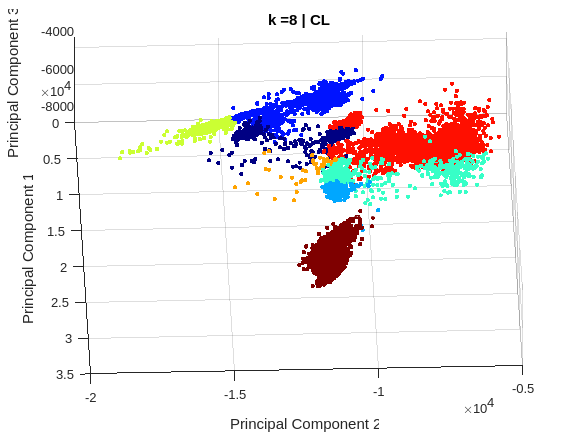

PCA_vs_cluster_plot_3D(Ground_truth,Total_idx_CL,Z,' CL')
view([88 72])

## **Weighted Pair Group Method Centroid (WPGMC)**

The WPGMC algorithm is less "sctrict" algorithm than complete link, and utilizes the following mathematical equation as a distance calculation for the linakge method:


$$d_{qs} = \frac{n_i}{n_i + n_j}d(C_i,C_s) +  \frac{n_j}{n_i + n_j}d(C_j,C_s) - \frac{1}{4}d(C_i,C_j)$$


Total_idx_WPGMC = [];
for i = [6,8]
    B = linkage(Z','median','euclidean');
    idx = cluster(B,'maxclust',i);
    Total_idx_WPGMC = cat(2,Total_idx_WPGMC,idx);
end

**Problem faced**

As its depicted below, WPGMC produced a  non-monotonic cluster tree with crossover, this means, as shown below that a clustering merge step $d_{qs} < max(d_{is}, d_{js})$ and thus the mathematical equation above didnt increase the similarty between levels, unlike the case of complete link and ward which always produce  a monotonic cluster tree. This translate to poor results for both k = 6 and k = 8, when compared to the 1st PC as well as the ground truth.

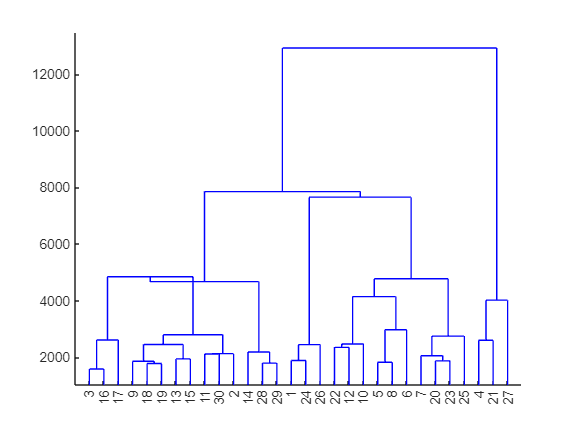

figure;
dendrogram(B);

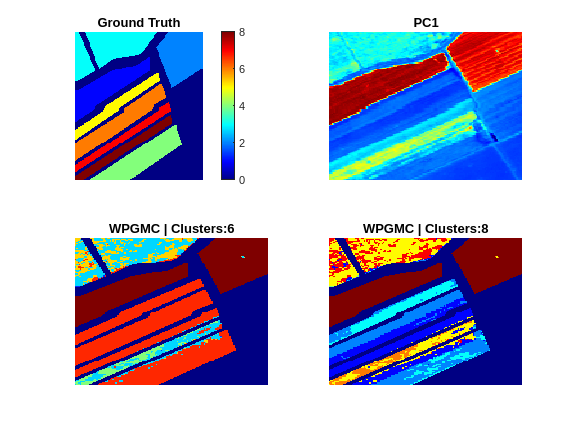

Clustering_Eval(Total_idx_WPGMC,'WPGMC',Z_total_cube,Salinas_Labels,existed_L)

# Quantative evaluation and comments on the performance.

## Cluster label matching problem

In order to accurately assess the performance of a clustering algorithm, it is important to align the predicted cluster labels with their corresponding ground truth labels. This is because there is no inherent connection between a partition of elements and a specific label, and even if two solutions match perfectly, the assigned cluster labels and ground truth labels may differ, making comparisons unreliable. To address this issue, the following steps were taken:

- Create a confusion matrix for the predicted cluster labels of the algorithm and the ground truth labels. This matrix has the unique cluster labels as row indices and the unique ground truth labels as column indices, and represents the counts of each label being matched in the dataset. It also has the added benefit of padding the matrix with 0's when the cluster predicted labels dont match in number with the actual labels, such as when k = 6. This keeps the matrix square which is important for the next step.

- Use this confusion matrix as input for a cost matrix (1 - Confusion matrix) in the Hungarian algorithm. This algorithm assigns the most optimal label matchings between the predicted cluster labels and ground truth labels, taking into account the cost matrix, it works best when the predicted labels match in number the ground truth labels (k = 8), but it gives adequate solutions for unequal numbers allowing us to evaluate the performanace of the algorithms with k=6.

## Quantative **Evaluation metric**

For evaluation between the ground truth partitions $P$ and the predicted clusters $C$ the Rand index is utilized.

The Rand index is defined as the ratio of the number of pairs of elements that are either in the same cluster in both data clusterings, or in different clusters in both data clusterings, to the total number of pairs of elements. Mathematically, it can be represented as:


$$\textrm{RI}=\left(a+b\right)/\left(a+b+c+d\right)$$


where:

- a: number of pairs of elements that are in the same cluster in $C$  and in the same group in $P$

- b: number of pairs of elements that are in the same cluster in $C$ and different groups in  $P$

- c: number of pairs of elements that are in different clusters in $C$ and to the sane group in $P$

- d: number of pairs of elements that are in different clusters in $C$ and in different groups in $P$

When the value of the Rand index is high, it indicates a strong agreement between the two data clusterings being compared, $P$ and $C$.

## Quantative evaluation

In order to obtain an accurate evaluation of the performance of the cost function optimization algorithms, they were run multiple times (20 times with the same user defined parameters as in the previous chapter, except the seed) and the average execution time and Rand Index were calculated. This was done to account for the randomness inherent in the cost function optimization algorithms. However, this step was not necessary for the hierarchical clustering algorithms because they are deterministic and therefore produce consistent results. For this purpose the `Qevaluation` function was coded, as seen in the final chapter of the notebook.

Below we present the quantative evaluation results for k = 6 and k = 8, both in the 204-Dimensions of the original dataset and in the 3-Dimensions fo the PCA projected dataset.

**Quantative evaluation in the 204-Dimensions of the original dataset for k = 6**

ill conditioned covariance matrix created for PBC full


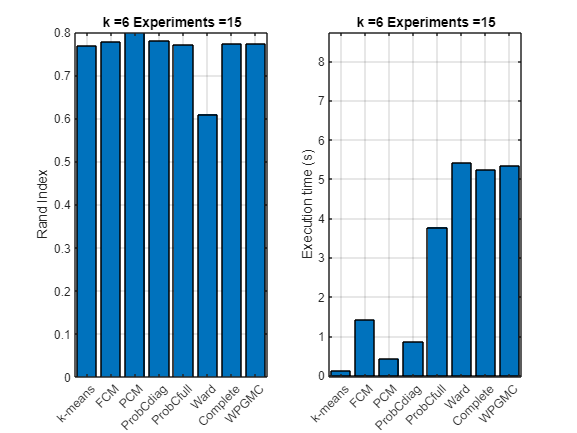

[algorithms,avg_RI_score,average_times] = Qevaluation(X,6,15,Ground_truth);

**Quantative evaluation in the 3-Dimensions of the PCA projected dataset for k = 6**

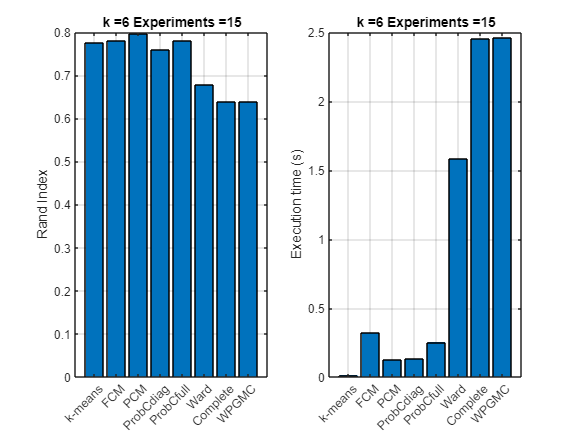

[algorithms,avg_RI_score,average_times] = Qevaluation(Z',6,15,Ground_truth);

**Quantative evaluation in the 204-Dimensions of the original dataset for k = 8**

ill conditioned covariance matrix created for PBC full
ill conditioned covariance matrix created for PBC full


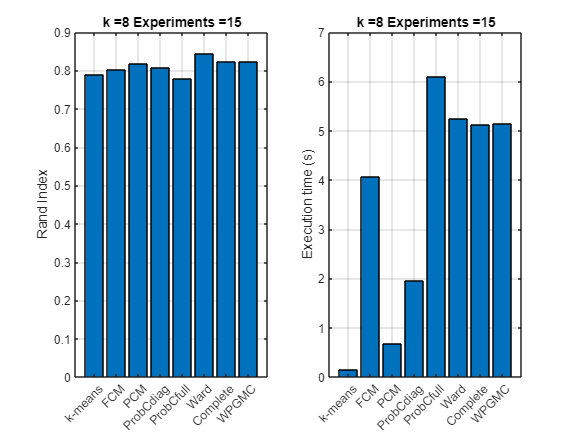

[algorithms,avg_RI_score,average_times] = Qevaluation(X,8,15,Ground_truth);

**Quantative evaluation in the 3-Dimensions of the PCA projected dataset for k = 8**

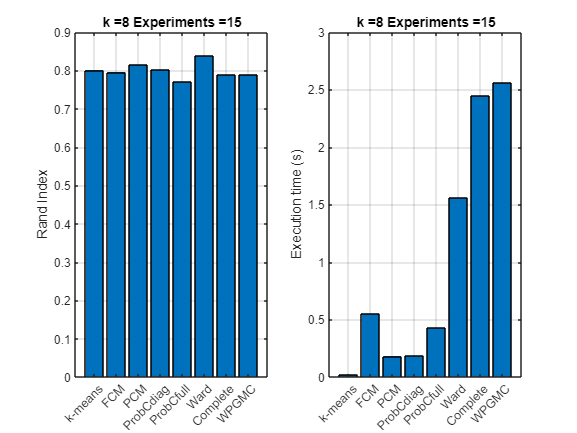

[algorithms,avg_RI_score,average_times] = Qevaluation(Z',8,15,Ground_truth);

## Comments on the quantative evaluation results

Its obvious that the dataset is comprised mostly with elipsoid and compact clusters with noise.

**Note:**

In this chapter its important to keep in  mind the intracisies of each of the above clustering algorithms, as discussed and visualized in the qualitative chapter. 

From the evaluation above the most important observations can be summed with the following list:

- The cost function optimization aglorithms performed very well across k = 6 and k =8 as well as in the 204-D and 3-D projected dataset. 

- The fuzzy, possibilsitic and probabilistic algorithms performed slightly better than the k-means.

- The ward algorithm performed poorly compared to the Complete link and WPGMC for k = 6 in the 204-D, but better than Complete link and WPGMC in the 3-D dataset for  k = 6. 

- The Complete link and WPGMC algorithms performed bad r for k =  6 at the PCA space but equally well at all the other conditions.

-  The ward algorithm performed the best for k = 8 both for the 204-D dataset and the projected 3-D dataset.

-  The probabilistic with diagonal covariance matrices performed better almost in all cases than the full covariance matrix probabilistic, especially in the 204-D dataset.

-  The possibilistic algorithm performs the best when compared with other cost function optimization algorithms

Possible explanations for each of these observations are:

-  The cost function optimization aglorithms (CFO) always produce a local optima for the specified number of clusters. If compact clusters exist in the dataset, across 15 experiments the local optima averaged out are bound to produce good resulsts when compared to the deterministic nature of hierarchical clustering algorithms which consider the whole clustering tree from each vector as a cluster to the final one cluster making it possible for certain merging steps to not be as optimal as others. This of course depens on the structure of the data points in the clustering space. 

- The 3-D PCA plot revealed that the dataset contains a significant amount of noise. This has a greater impact on the hard clustering approach of k-means than on the soft clustering of fuzzy-c means and possibilistic c-means, which can assign points to clusters with varying degrees of membership. The probabilistic c-means algorithm can also filter out the noise by treating it as its own separate distribution, resulting in more accurate predictions for the remaining clusters.

- Keep in mind that the 3-D projected with the PCA dataset has nearly all the variance captured in a much smaller space, also keep in mind that the dataset is noisy. Thus the distance based hierarchial aglorithms ( Complete link , WPGMC)  perform worse with the overlapping noise in the smaller space and the ward algorithm based on variance  performes better since it is defined will in the 3-D PCA space.

- This is a result based on the comments in 3. above. With the cutoff at k = 6 at the PCA space with noise overlap many clusters were merged wrong by the distance based Complete link and WPGMC, however at k = 8 with the additonal merging steps these algortihms managed to produce a better result. For k = 6 at the 204-D dimensions Complete link and WPGMC do not face this problem since the clusters and the noise are well seperated in the much larger space.

- The Ward algorithm by using the minimization of with-in cluster variance as a metric matches very well the clustering characteristic of the dataset for this specific cluster number which are preserved both in the 204-D space and the 3-D space.

- This means that the complexity of the full covariance Mixture models was not needed for this dataset and in most cases it led to overfitting. Especially in the higher 204-Dimensions of the orginal dataset many linear dependencies exist resulting in ill-conditioned full covariance matrices. 

- As mentioned before, the dataset contains a significant amount of noise. The possibilistic c-means (PCM) algorithm is well-suited to handle this type of data because it can assign points to clusters with varying degrees of membership. This means that points in dense areas, which are likely to be true cluster members, can be assigned with a high degree of membership, while points in noisy areas can be assigned with a lower degree of membership or even not assigned to any cluster at all. This allows PCM to partition the dataset effectively and accurately, even in the presence of noise, by assigning only the most important points as representatives of the clusters. PCM can also reduce the number of representatives (coinciding representatives) if its necessary to achieve a better clustering of the dataset.

Considering the execution time, of course the hierarchical algorithms were much slower having to compute the pairwise distance between all of the observations in the dataset. Of course the hard k-means algorithm having to compute only the mean dsitance  between representatives and points performs the fastest.

# Functions utilized 

**"pca_fun.m" (c) 2010 S. Theodoridis, A. Pikrakis, K. Koutroumbas, D. Cavouras**

**"possibi.m" (c) 2010 S. Theodoridis, A. Pikrakis, K. Koutroumbas, D. Cavouras**

**"munkres" (c) 2009, Yi Cao**

# Function created

**Function to plot  clustering results vs the Ground truth PCA in the space of the first 2 PCs.**

function [] = PCA_vs_cluster_plot_2D(Ground_Truth,idx,Z,algorithm)   
     figure;
     subplot(1,3,1);
     hold on 
     scatter(Z(1,:),Z(2,:),'CData',Ground_Truth,'Marker','.')
     colormap("jet")
     colorbar
     grid on 
     title('Ground Truth')
     xlabel('Principal Component 1')
     ylabel('Principal Component 2')
     hold off
     subplot(1,3,2);
     hold on 
     scatter(Z(1,:),Z(2,:),'CData',idx(:,1),'Marker','.')
     colormap("jet")
    title(strcat('k = ',int2str(length(unique(idx(:,1)))),' | ',algorithm))
     grid on 
     xlabel('Principal Component 1')
     ylabel('Principal Component 2')
     hold off
     subplot(1,3,3);
     hold on 
     scatter(Z(1,:),Z(2,:),'CData',idx(:,2),'Marker','.')
     colormap("jet")
     title(strcat('k = ',int2str(length(unique(idx(:,2)))),' | ',algorithm))
     grid on 
     xlabel('Principal Component 1')
     ylabel('Principal Component 2')
     hold off 
 end

**Function to plot  clustering results vs the Ground truth PCA in the space of the first 3 PCs.**

 function [] = PCA_vs_cluster_plot_3D(Ground_Truth,idx,Z,algorithm)   
     figure;
     scatter3(Z(1,:),Z(2,:),Z(3,:),'CData',idx(:,2),'Marker','.')
     colormap("jet")
     title(strcat('k = ',int2str(length(unique(idx(:,2)))),' | ',algorithm))
     grid on 
     xlabel('Principal Component 1')
     ylabel('Principal Component 2')
     zlabel('Principal Component 3')
     view([58 -6])
 end

**Function to plot the Ground Truth image and the first principal componenet vs the clustering results**

function [] = Clustering_Eval(Total_idx,algorithm,Z_total_cube,Salinas_Labels,existed_L) 
figure;
colormap("jet");
subplot(2,2,1);
imagesc(Salinas_Labels)
axis off 
title("Ground Truth")
colorbar
subplot(2,2,2)
imagesc(Z_total_cube(:,:,1))
axis off 
title("PC1")
count  = 3;
for i = 1:(size(Total_idx,2))
    hold on
    cl_label = Total_idx(:,i);
    cl_label_tot=zeros(150*150,1);
    cl_label_tot(existed_L)=cl_label;
    im_cl_label=reshape(cl_label_tot,150,150);
    subplot(2,2,count);
    imagesc(im_cl_label)
    axis off
    title(strcat(algorithm,' | Clusters: ', int2str(length(unique(cl_label)))))
    count  = count + 1;
end
end

**Quantative Evaluation Function.**

function [algorithms,avg_RI_score,average_times] = Qevaluation(X,m,runs,Ground_truth)

%initial matrices
%kmeans
U_kmeans_total = [];
kmeans_time = [];
%FCM
U_FCM_total = [];
FCM_time = [];
%PCM
U_PCM_total = [];
PCM_time = [];
%Probabilistic_diag
U_PBCdiag_total = [];
PBCdiag_time = [];
%Probabilistic_full
U_PBCfull_total = [];
PBCfull_time = [];

% no need for arrays for the hieararchical since they 
% are deterministic 

    for i= 1:runs
     rand('seed',i + 42)
     %K means 
     tic ;
     U_kmeans = kmeans(X,m);
     tend = toc;
     kmeans_time = cat(1,kmeans_time,tend);
     U_kmeans_total = cat(2,U_kmeans_total,U_kmeans);
     %FCM
     options = [2 100 1e-5 0];
     tic;
     [~,U_FCM] = fcm(X,m,options);
     tend = toc;
     [~,index] = max(U_FCM);
     FCM_time = cat(1,FCM_time,tend);
     U_FCM_total = cat(2,U_FCM_total,index');
     %PCM
     eta = mean((sum(X - mean(X)).^2));
     eta_m = ones(1,m)*eta;
     tic;
     [idx,~] = possibi(transpose(X), m, eta_m, 2, i, 3);
     tend = toc;
     PCM_time = cat(1,PCM_time,tend);
     [~,index] = max(idx,[],2);
     U_PCM_total = cat(2,U_PCM_total,index);
     %Probabilistic diagonal
     tic ;
     GMModel = fitgmdist(X,m,'CovarianceType','diagonal');
     [idx, ~] = cluster(GMModel,X);
     tend = toc;
     PBCdiag_time = cat(1,PBCdiag_time,tend);
     U_PBCdiag_total = cat(2,U_PBCdiag_total,idx);
     %Probabilistic full
     try
         tic ;
         GMModel = fitgmdist(X,m,'CovarianceType','full');
         [idx, ~] = cluster(GMModel,X);
         tend = toc;
         PBCfull_time = cat(1,PBCfull_time,tend);
         U_PBCfull_total = cat(2,U_PBCfull_total,idx);
     catch ;disp('ill conditioned covariance matrix created for PBC full');
         PBCfull_time = cat(1,PBCfull_time,tend);
         U_PBCfull_total = cat(2,U_PBCfull_total,idx);
     end
    end
    
     %Hierachical are deterministic no need to be averaged out over multiple runs
     tic; 
     B = linkage(X,'ward','euclidean');
     idx = cluster(B,'maxclust',m);
     tend = toc;
     Ward_time = tend;
     U_Ward_total = idx;
     %Complete
     tic; 
     B = linkage(X,'complete','euclidean');
     idx = cluster(B,'maxclust',m);
     tend = toc;
     Cl_time = tend;
     U_Cl_total = idx;
     %WPGMC
     tic; 
     B = linkage(X,'complete','euclidean');
     idx = cluster(B,'maxclust',m);
     tend = toc;
     wpgmc_time = tend;
     U_wpgmc_total = idx;
     
         
 U_Results = {U_kmeans_total,U_FCM_total,U_PCM_total,U_PBCdiag_total,U_PBCfull_total,U_Ward_total,U_Cl_total,U_wpgmc_total};
 Times = [kmeans_time FCM_time,PCM_time PBCdiag_time PBCfull_time];

 
%RI score calculation for CFO
RI_score = zeros(runs,5);

for i = 1:5
    for j= 1:runs
        temp = cell2mat(U_Results(i));
        % 1 - Confusion matrix to feed into the munkres algorithm
        C = confusionmat(temp(:,j),Ground_truth);
        [index,~] = munkres(1-C);
        %Munkres algorithm run
        for k = 1:8
            index_revalued = temp(:,j) == k;
            temp(index_revalued,j) = index(k);
        end
        RI_score(j,i) = rand_index(temp(:,j),Ground_truth);
    end
end

algorithms = {'k-means','FCM','PCM','ProbCdiag','ProbCfull','Ward','Complete','WPGMC'};

% Average out CFO scores
avg_RI_score = mean(RI_score,1);

%Average out CFO run time calculation
average_times = mean(Times,1);

%Hierarchical scores
for i = 6:8
     temp = cell2mat(U_Results(i));
        % 1 - Confusion matrix to feed into the munkres algorithm
        C = confusionmat(temp,Ground_truth);
        [index,~] = munkres(1-C);
        for k = 1:8
            index_revalued = temp == k;
            temp(index_revalued) = index(k);
        end
        avg_RI_score = cat(2,avg_RI_score, rand_index(temp,Ground_truth));
end

average_times = cat(2,average_times,[Ward_time Cl_time wpgmc_time]);


%Plot the results
figure;
subplot(1,2,1);
X_axis = categorical(algorithms);
X_axis= reordercats(X_axis,algorithms);
Y_axis = avg_RI_score;
bar(X_axis,Y_axis)
yticks([0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1])
grid on
title(strcat('k = ',int2str(m),' Experiments = ',int2str(runs)));
ylabel("Rand Index")
subplot(1,2,2);
X_axis = categorical(algorithms);
X_axis = reordercats(X_axis,algorithms);
Y_axis = average_times;
bar(X_axis,Y_axis)
grid on
title(strcat('k = ',int2str(m),' Experiments = ',int2str(runs)));
ylabel("Execution time (s)")
end